%calculating the mean first passage time analytically/numerically 
%to investigate effect of incumbent and invader toehold lengths on RNA/DNA
%toehold exchange kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

%g = 2 %define invader toehold length
%g2 = 6 %define incumbent toehold length

g2 = 6



R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -0.3*R*temp

dGrd = -0.1777

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(6,15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(6, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(6, 15)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through incumbent toehold lengths
for g2 = 2:7
    bg2 = b + g2 %define branch migration domain + incumbent toehold length
    %loop through invader toehold lengths
    for g = 1:15
        
        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
        k_Cf = k_bp * exp(-dGbm/(R*temp))
        k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
        k_DEij = k_bp * exp(dGbp/(R*temp));
        k_DEji = k_bp;
        k_EF = k_bp * exp(dGbp/(R*temp));
        k_FE = 0
        k_FF = 1    
    
        %create arrays of forward and reverse transition rates
        if g == 1
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
        
            %define spontaneous incumbent dissociation rate
            Koff = [repmat(0, [1, g2+1])];
            for n = g2+1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff = horzcat(Koff, [0, 0])
        
        else
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
            %define spontaneous incumbent dissociation rate
            Koff = [repmat(0, [1, g2+1])]; 
            for n = g2+1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
        end
    
        Pn_jN_1 = zeros(1,numel(Kf))
        jn_jN_1 = zeros(1,numel(Kf))
        Pn_jN_1 (1) = 0;
        jn_jN_1 (1) = 1;
        
        %calculate flux between each state
        for Pn = 2:numel(Kf)
            Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
            jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
        end
        
        first_pass_time (g2-1, g) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time
        k_eff (g2-1, g) = 1/(first_pass_time (g2-1, g)*(5*10^-8)); %calculate effective rate constant
        prob_unbound(g2-1, g) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate prob of being in unbound state
    end
end

bg2 = 22

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+06 *

    0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0009    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    6.8458         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219         0


ans = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


ans = 	1.0e+07 *

         0    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans = 	1.0e+04 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    6.8458    0.4086         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


ans = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


ans = 	1.0e+07 *

         0    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    6.8458    0.4086    0.0249         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219         0


ans = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


ans = 	1.0e+07 *

         0    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans = 	1.0e+04 *

         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    6.8458    0.4086    0.0249    0.0020         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219         0


ans = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


ans = 	1.0e+07 *

         0    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans = 	1.0e+04 *

         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+04 *

    6.8458    0.4086    0.0249    0.0020    0.0006         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0007


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 23

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0009    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219         0


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219         0


ans =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000         0


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000         0


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000         0


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000         0


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000         0


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0007


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0    2.2631    0.1821    0.0147    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 24

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0009    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219         0


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219         0


ans =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0007


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0  182.0888   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 25

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0009    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219         0


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219         0


ans =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0007


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0   14.6508    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 26

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0009    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219         0


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219         0


ans =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


ans =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005    0.0005         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0007


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0    1.1788    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     6.8458    0.4086    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8494    0.4088    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8517    0.4089    0.0249    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    6.8735    0.4102    0.0250    0.0020    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    7.1446    0.4264    0.0259    0.0021    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 27

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0009    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219         0


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219         0


ans =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0000


ans =          0    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000         0


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


ans =          0    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307    0.8305         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0007


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307    0.8305    0.8305         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307    0.8305    0.8305    0.8305         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307    0.8305    0.8305    0.8305    0.8305         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307    0.8305    0.8305    0.8305    0.8305    0.8305         0         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307    0.8305    0.8305    0.8305    0.8305    0.8305    0.8305         0         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307    0.8305    0.8305    0.8305    0.8305    0.8305    0.8305    0.8305         0


k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


ans =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


ans =          0    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Koff =          0         0         0         0         0         0         0         0    0.0948    0.0076    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.6846    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6849    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6852    0.0409    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.6874    0.0410    0.0025    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.7145    0.0426    0.0026    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0513    0.0627    0.0038    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


prob_unbound =     1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9997    0.9990    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988    0.9988
    1.0000    1.0000    1.0000    0.9996    0.9989    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987    0.9987
    1.0000    1.0000    0.9999    0.9993    0.9978    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975    0.9975
    1.0000    1.0000    0.9996    0.9955    0.9852    0.9829    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828    0.9828
    1.0000    0.9998    0.9972    0.9622    0.8597    0.8326    0.8307    0.8305    0.8305    0.8305    0.8305    0.8305    0.8305    0.8305    0.8305


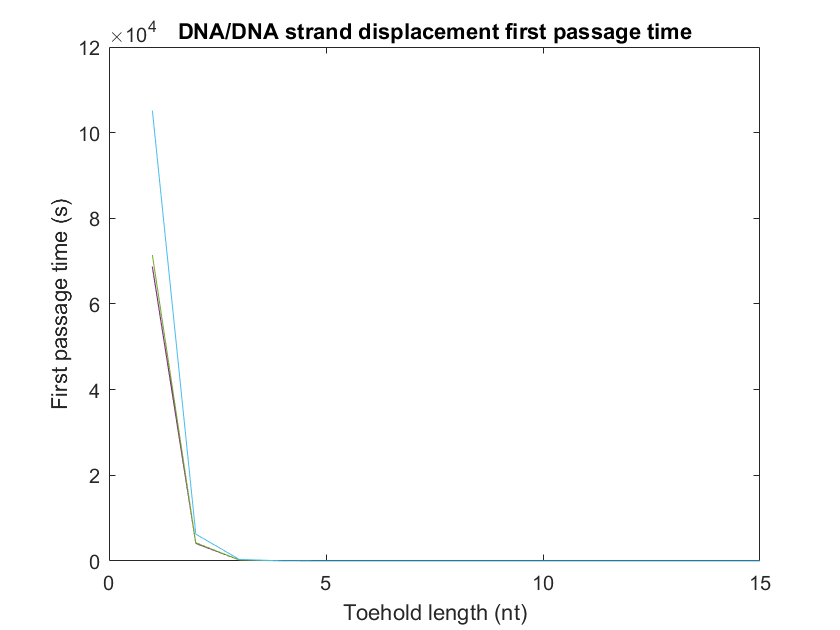

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

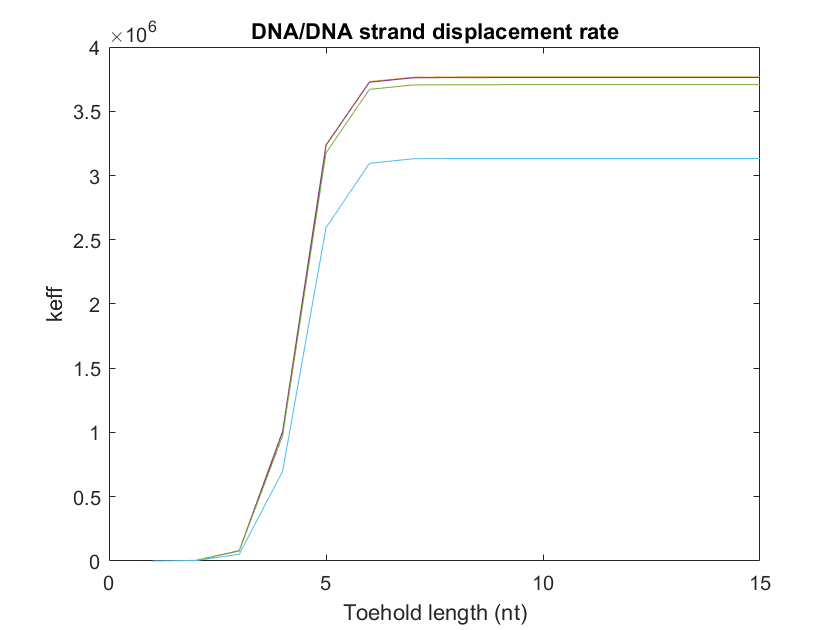


plot(1:15, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

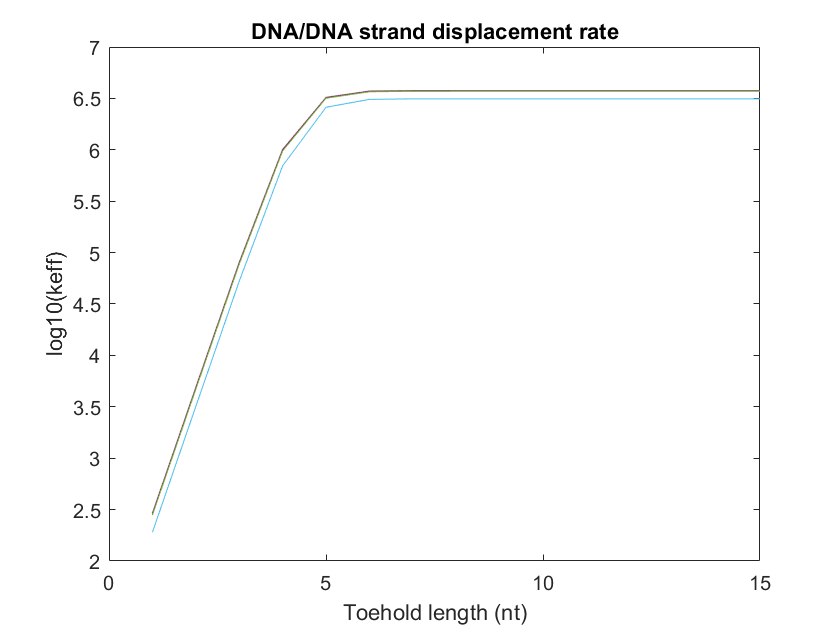


plot(1:15, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  